The experiment consisted of a circular trajectory and arm deployment. This was to validate the new laboratory software as well as to test the added sensors. First we load the data.

load('RED_EXP_Struct');
load('dataPacket_SIM.mat');

Now we plot the attitude from the IMU and PhaseSpace for the RED platform.

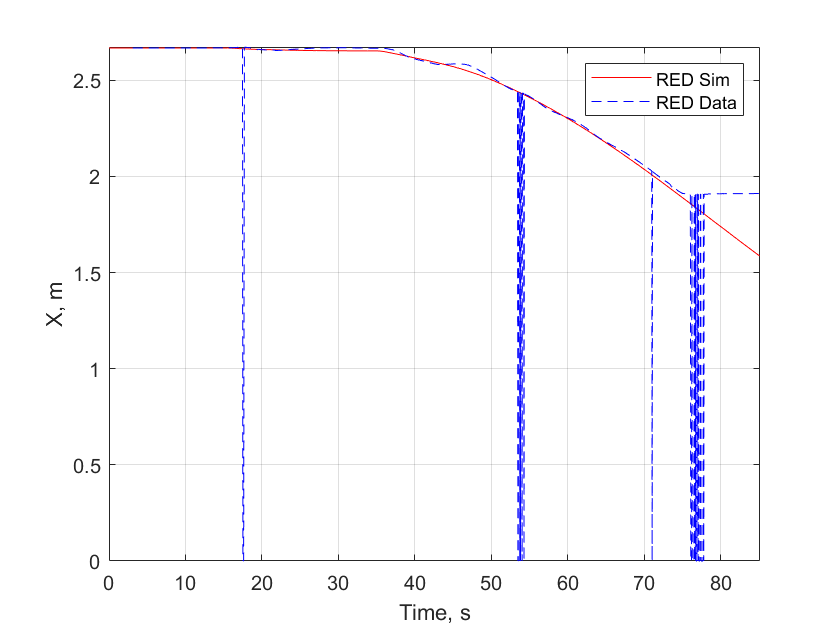

figure()
plot(dataClass.Time_s(1:end), dataClass.RED_Px_m(1:end),'-r')
hold on
grid on
axis tight
plot(RED_Validation.Time_s(225:end), unwrap(RED_Validation.RED_Px_m(225:end)),'--b')
xlabel('Time, s')
ylabel('X, m')
legend('RED Sim','RED Data','location','northeast')

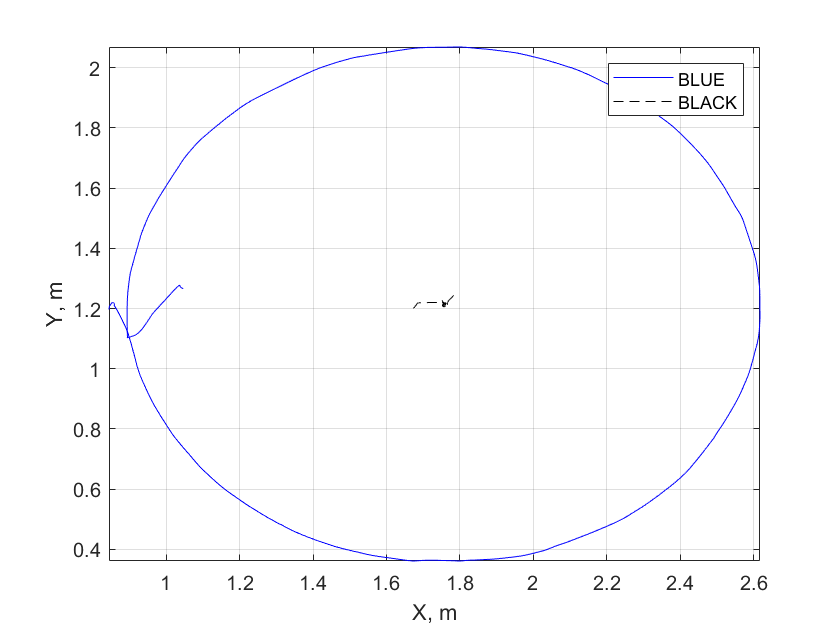

figure()
plot(dataClass.BLUE_Px_m(400:end), dataClass.BLUE_Py_m(400:end),'-b')
hold on
grid on
axis tight
plot(dataClass.BLACK_Px_m(200:end), dataClass.BLACK_Py_m(200:end),'--k')
xlabel('X, m')

ylabel('Y, m')
legend('BLUE','BLACK','location','northeast')

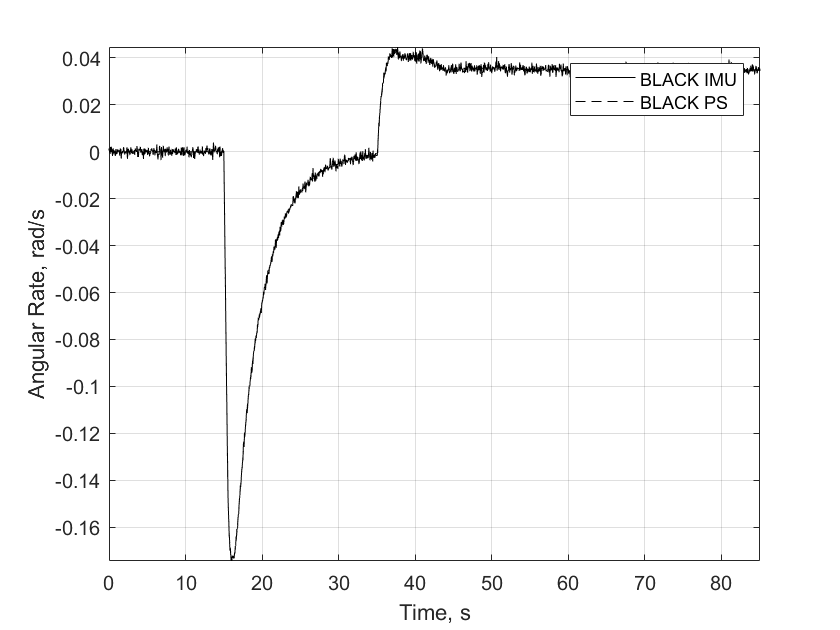

figure()
plot(dataClass.Time_s,dataClass.RED_GyroZ_Raw_radpers,'-k')
hold on
grid on
axis tight
plot(dataClass.Time_s, dataClass.RED_RzD_radpers,'--k')
xlabel('Time, s')

ylabel('Angular Rate, rad/s')
legend('BLACK IMU','BLACK PS','location','northeast')